# Seminar 4 - ARX

**Authors:** prof. Ing. Vladimír Havlena, CSc., Ing. David Vošahlík

## Introduction

The Auto Regressive model with eXternal input (ARX) is used for parameter estimation of a dynamical model, where the parameters are not known. This grey box approach can be used in many scenarios. Imagine that you have a model from known physical first principles and you want to estimate its parameters from measured data. Another example is if you have time varying (slowly) parameters and you want to reflect that in your controller. 

## ARX Batch identification

In this section the estimation from measured data will be executed in a batch. In this case the ARX parameter estimation is linear regression. In this section we will inspect a model of a linearized chemical process that is described by a transfer function:


$$H\left(s\right)=\frac{{b_0 s}^2 +b_1 s+b_2 }{{{s^3 \;+\;a}_1 s}^2 +a_2 s+a_3 }$$


- Discretize the system using the sampling time $T_s =0\ldotp 2s$

- Generate experiment data also with measurement noise (do not forget about noise shaping)

- Construct the regressor and do the parameters estimate

- Compare the values of the parameters with the real ones that were used to generate the data

- change sample size and check the estimation performance

- use both algorithms for parameter estimation - QR decompozition and pseudoinverse

- Change the parameters of the estimation algorithm and observe the behavior:

- ARX model structure - change the *na* and *nb* values

- number of samples

- noise variance

- feed the system with unit step. Will it be possible to do the batch estimate using this input?

For this task modify the prepared function *ARXBatch *that is in Appendix

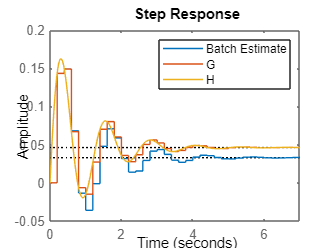

%% ARX Batch parameter identification

ARXBatch('plot', 1, 'na', 2, 'nb', 4, 'n_samples',10000);

### Estimated model quality

Here your task will be to evaluate the estimated batch model quality using the residual sum of squares. Your task will be to:

- Set different model structures and compare the estimated noise variance. Don't forget to use only proper transfer function.

- What model structure would you use for real time implementation?

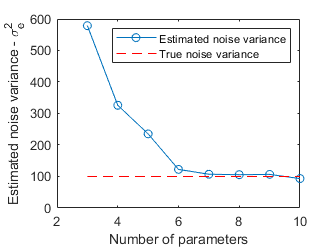

sigmaEst = nan(10,1);
for i = 2:5
    for j = 1:5
        if i >= j
            [Y, Z, theta] = ARXBatch('na', i, 'nb', j);
            sEst = 1/(numel(Y) - i - j)*(Y - Z*theta)'*(Y - Z*theta);
            sigmaEst(i + j) = min(sigmaEst(i + j), sEst);
        end
    end
end
figure;
plot(sigmaEst, '-o');
hold on;
line([3 10], [100 100], 'Color','red','LineStyle','--');
legend('Estimated noise variance', 'True noise variance')
ylabel('Estimated noise variance - \sigma_e^2');
xlabel('Number of parameters');

## Appendix

function [Y, Z, theta, P] = ARXBatch(varargin)
% You can enforce the estimated model structure with the arguments
% First argument sets the number of parameters in denominator of the TF
% Second argument sets the number of parameters in numerator of the TF


p = inputParser;
addParameter(p,'na',3, @isnumeric);
% Be carful of how the nb is defined. In this script nb is number of b parameters.
addParameter(p,'nb',3, @isnumeric);
addParameter(p,'plot',0, @isnumeric);
addParameter(p,'n_samples',100, @isnumeric);
parse(p, varargin{:});
na = p.Results.na;
nb = p.Results.nb;
plot = p.Results.plot;
n_samples = p.Results.n_samples;

[u, y, Ts, G, H] = generate_data(n_samples);





% Output vector
Y=y(1 + max(na,nb):n_samples);

% Regressor
Z=zeros(n_samples - max(na,nb),na+nb);

for i=1 + max(na,nb):size(Z,1) + max(na,nb)
    Z(i - max(na,nb),:)=[-y(i - 1:-1:i-na)', u(i:-1:i-nb + 1)];
end


% Batch identification (least squares)
% theta_batch = pinv(Z)*Y
% badly conditioned formula
theta_batch = (Z'*Z)\Z'*Y;
P_batch = inv(Z'*Z);
% QR algorithm solution
[Q,R] = qr(Z);
theta_batch = R\Q'*Y;
P_batch = inv(R'*R);

theta = theta_batch;
P = P_batch;
if plot
    % Plot result
    G_batch = tf(theta_batch(na+1:end)',[1 theta_batch(1:na)'],Ts,'Variable','z^-1');
    G_batch.Name = 'Batch Estimate';
    figure;
    step(G_batch)
    hold on;
    step(G)
    step(H)
    legend show
    fix_ylim = ylim;
end
end

function [u, y, Ts, G, H] = generate_data(n_samples)
a = [1     7    36   130];
b = [1     5     6];

Ts = 0.2;
H = tf(b, a);
G = c2d(H, Ts);                         % deterministic transfer function
He = tf(1, G.den{1}, Ts);               % noise transfer function

% generate input data and simulate the system
sig = 10;
u = 150.*randn(1,n_samples);
y = lsim(G, u, cumsum(Ts*ones(1, n_samples)) - Ts) + lsim(He, sig.*randn(n_samples, 1), cumsum(Ts*ones(1, n_samples)) - Ts);
end